v_r = VideoReader("bicepCurls.mp4");
v_w = VideoWriter("curl_v_reo_result");
of = opticalFlowFarneback;

testFrameno = 1

testFrameno = 1

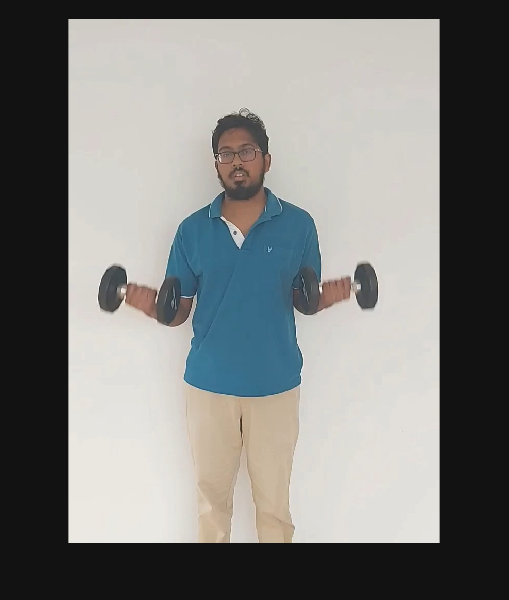

testFrame = read(v_r, testFrameno);
imshow(testFrame)

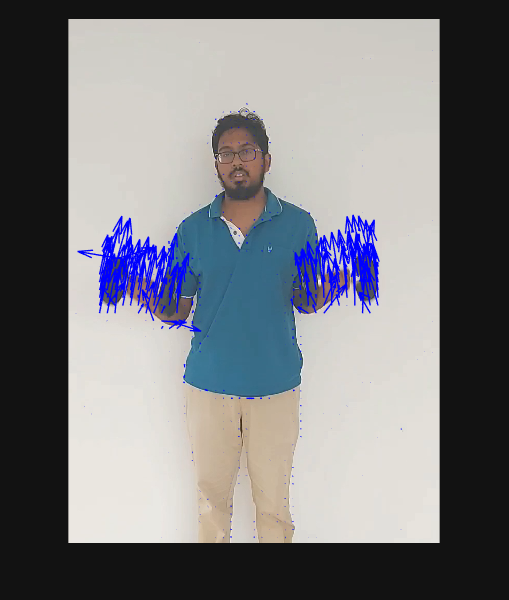

estimateFlow(of, im2gray(testFrame));

nextFrame = read(v_r, testFrameno + 1);
testFlow = estimateFlow(of, im2gray(nextFrame));
imshow(nextFrame);
hold on;
plot(testFlow, "DecimationFactor", [15,15], "ScaleFactor", 5)
hold off;

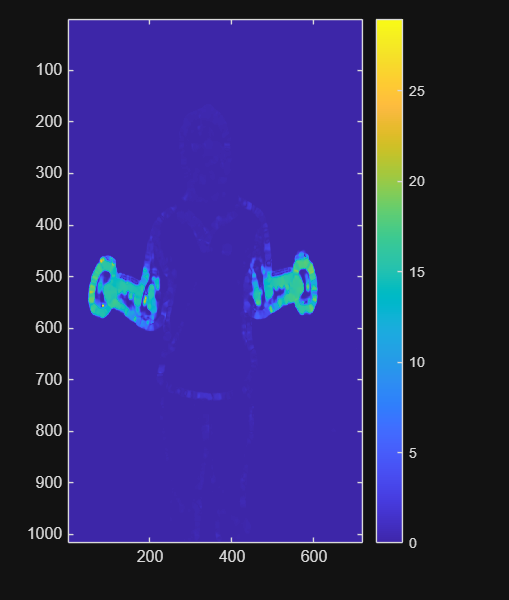

testFlow;
imagesc(testFlow.Magnitude);
colorbar

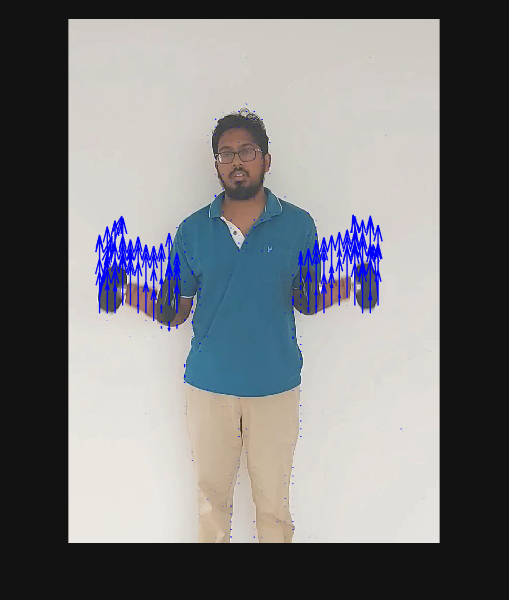

magThresh = 17;
threshFlow = testFlow.Magnitude >= magThresh;

VxThresh = testFlow.Vx;
VxThresh(~threshFlow) = 0;
VyThresh = testFlow.Vy;
Vy(~threshFlow) = 0;
magThreshFlow = opticalFlow(VxThresh, VyThresh);

imshow(testFrame);
hold on;
plot(magThreshFlow, "DecimationFactor", [15 15], "ScaleFactor", 5);
hold off;

movObjs = regionprops("table",mask,flow.Magnitude,["MeanIntensity","BoundingBox"]);

if ~isempty(movObjs)
    labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,...
        "Velocity: " + string(round(movObjs.MeanIntensity,2)));
end
imshow(labelFrame)

Unrecognized function or variable 'labelFrame'.

open(vidOut)

Unrecognized function or variable 'vidOut'.

writeVideo(vidOut, labelFrame)

for ii = 3:v_r.NumFrames
    frame = read(v_r,ii);
    flow = estimateFlow(of,im2gray(frame));
    mask = flow.Magnitude > magThresh;
    se = strel("disk",8,0);
    mask = imopen(mask,se);
    mask = imclose(mask,se);
    mask = imfill(mask,"holes");
    mask = bwareafilt(mask,[800, Inf]);
    movObjs = regionprops("table",mask,flow.Magnitude,"MeanIntensity","BoundingBox");
    movObjs(movObjs.MeanIntensity < magThresh,:) = [];
    if ~isempty(movObjs)
        labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,...
        "Velocity: " + string(round(movObjs.MeanIntensity,2)));
    end
    imshow(labelFrame)
    imshow(frame)
    writev_reo(v_w,labelFrame)
end